Load robot model, set joint angles for home position

clear, clc, close all;
robot = importrobot("C:\Users\atjensvo\cernbox\Documents\MATLAB\Collision_test.urdf", "DataFormat", "row");
robot.DataFormat = 'row';

q_home = [0 0 0 0 0 0 0 0 0];
eeName = "Tool_1";
config = q_home;

Show arm in home position

figure;
show(robot,q_home, Visuals="off", Collisions="on");
hold on

Generate environment

collisionCylinders = {
    collisionCylinder(0.457, 8.0),  % Main Pipe
    collisionCylinder(0.044, 0.3),  % Front BLM
    collisionCylinder(0.044, 0.3),  % Back BLM
    collisionCylinder(0.350, 1.0),  % First Obstacle
    collisionCylinder(0.350, 1.0)   % Second Obstacle
};

cylinderPoses = [
    -0.958, 4.260, -1.707, 1, 0, 0, pi/2; 
    -0.458, 2.015, -1.627, 1, 0, 0, pi/2;
    -1.456, 6.921, -1.627, 1, 0, 0, pi/2; 
    -0.952, 5.400, -0.986, 1, 0, 0, 0;
    -0.952, 6.900, -0.986, 1, 0, 0, 0
];

for i = 1:length(collisionCylinders)
    P = trvec2tform(cylinderPoses(i, 1:3));
    R = axang2tform(cylinderPoses(i, 4:7));
    collisionCylinders{i}.Pose = P * R;
    show(collisionCylinders{i});
end

Define goal poses

goalPoses = [
          %-0.000, 0.000, -2.400, 1, 0, 0, 0;  % Start
          -0.476, 2.015, -1.400, 1, 0, 0, 0;  % Front BLM
          -0.476, 6.200, -1.400, 1, 0, 0, 0;  % Front Obstacles
          -0.800, 6.400, -1.000, 1, 0, 0, 0;  % Between Obstacles
          -1.100, 6.200, -1.000, 1, 0, 0, 0;  % Back Obstacles
          -1.469, 6.400, -1.400, 1, 0, 0, 0;  % Back Obstacles
          -1.469, 6.921, -1.400, 1, 0, 0, 0;  % Back BLM
            ];

disp('Plotting all target poses...');

Plotting all target poses...


for i = 1:size(goalPoses, 1)
    pos = goalPoses(i, 1:3);
    rot = goalPoses(i, 4:7);
    poseTF = trvec2tform(pos) * axang2tform(rot);
    
    plotTransforms(pos, tform2quat(poseTF), "FrameSize", 0.1);
    text(pos(1), pos(2), pos(3), sprintf('Pose %d', i), 'FontSize', 10, 'Color', 'r');
end
disp('All target poses plotted. Press any key to start robot motion.');

All target poses plotted. Press any key to start robot motion.


pause('on');
pause;

Create RRT trajectory planner

planner = manipulatorRRT(robot,collisionCylinders);
planner.SkippedSelfCollisions = 'parent';
planner.EnableConnectHeuristic = false

planner =   manipulatorRRT with properties:

      MaxConnectionDistance: 0.1000
              MaxIterations: 10000
     EnableConnectHeuristic: 0
         ValidationDistance: 0.0100
    WorkspaceGoalRegionBias: 0.5000
        IgnoreSelfCollision: 0
      SkippedSelfCollisions: 'parent'


planner.MaxConnectionDistance = 0.2;
planner.ValidationDistance = 0.1;

Create IK solver

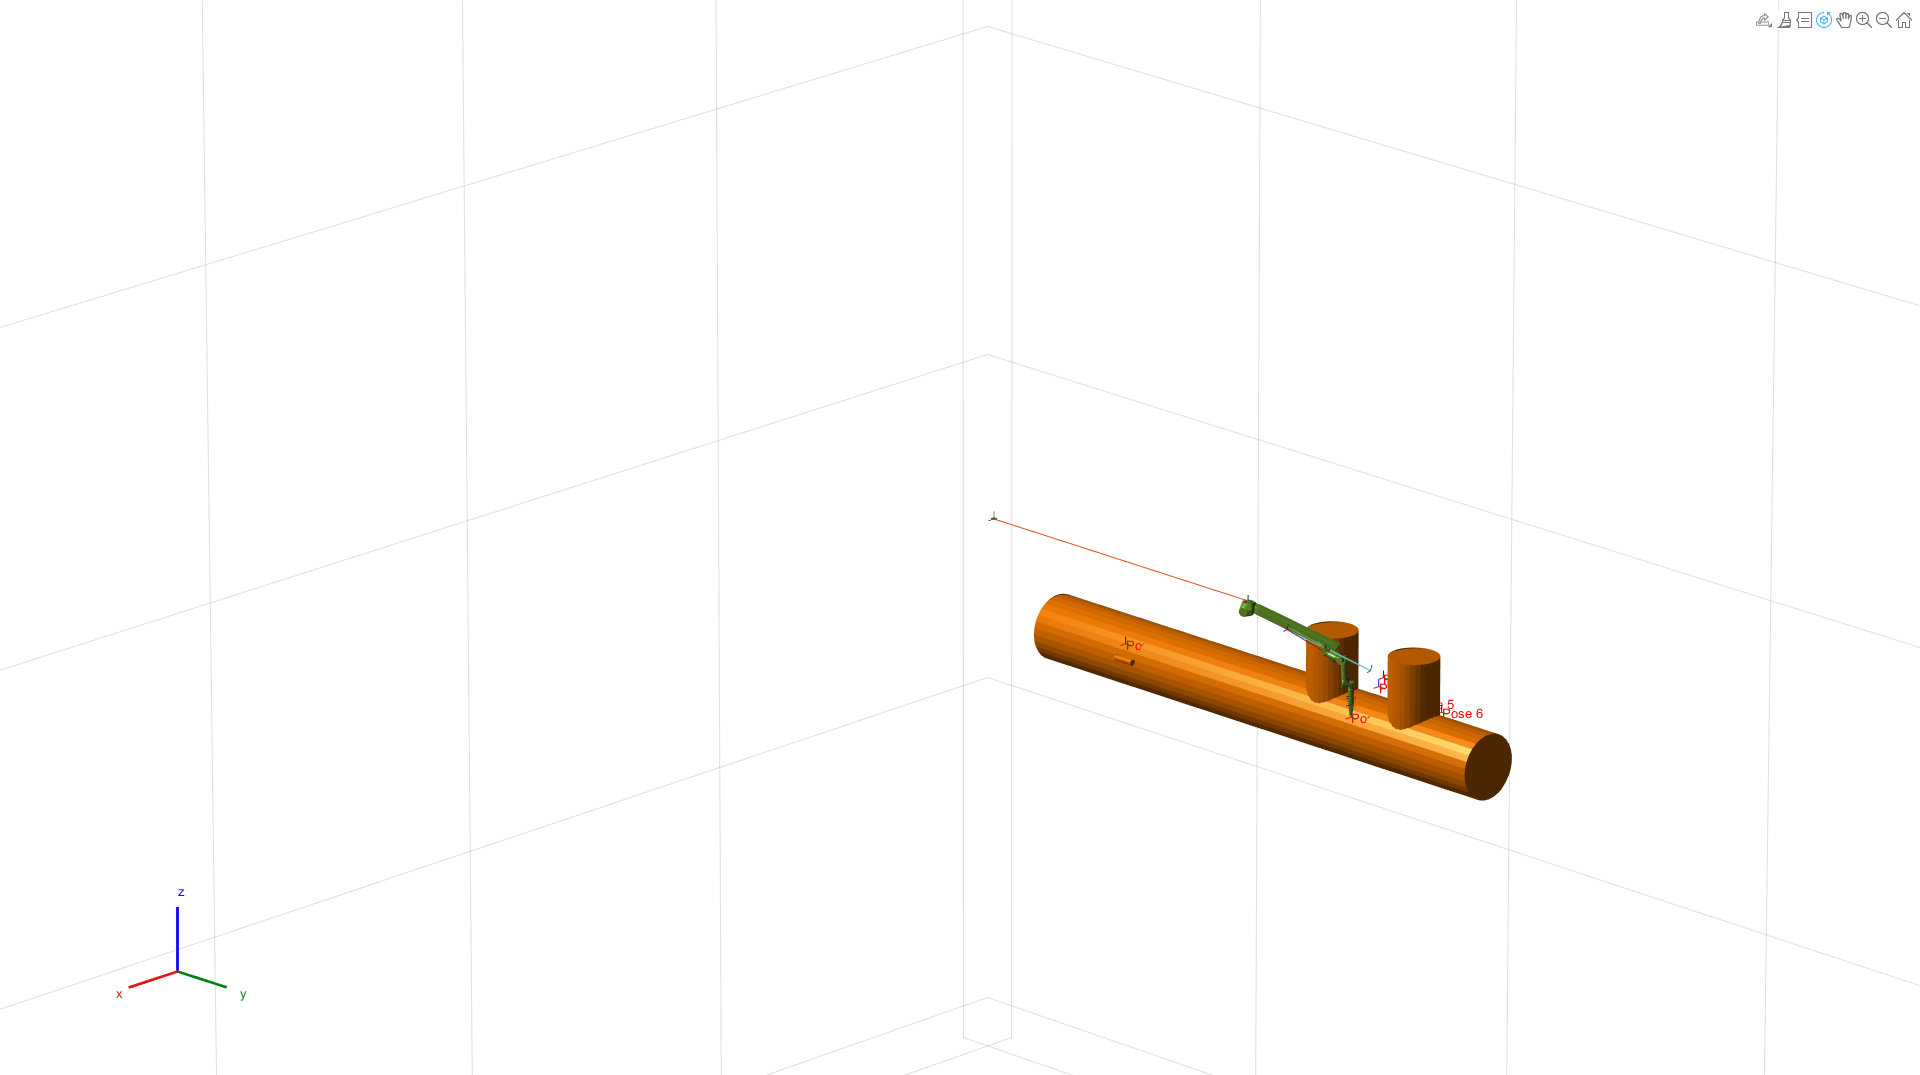

pose reached. Press any key to move to next.


pose reached. Press any key to move to next.


Error using robotics.manip.internal.error (line 19)
The goal configuration of the robot is in self collision.

Error in manipulatorRRT/validateInputConfiguration (line 472)
                    robotics.manip.internal.error(...

Error in 

gik = generalizedInverseKinematics('RigidBodyTree', robot);
gik.ConstraintInputs = {'position', 'orientation'};
currentConfig = config;  % Start with home position

% Define Pose goals
pos_goal = constraintPositionTarget(eeName);
ori_goal = constraintOrientationTarget(eeName);

% Set joint weighting for preferred motion
jointWeights = [1, 0.5, 0.5, 1, 1, 1, 1, 1, 1]; 
%gik.SolverParameters.
%gik.SolverParameters.Weights = jointWeights;

% Loop through goal poses
for i = 1:size(goalPoses, 1)
    position = goalPoses(i, 1:3);
    orientation = goalPoses(i, 4:7);

    % Convert to transformation matrix
    goalPose = trvec2tform(position) * quat2tform(orientation);

   % Set constraints
    pos_goal.TargetPosition = position;
    ori_goal.TargetOrientation = orientation; 

    % Solve IK 
    [goalConfig, solInfo] = gik(currentConfig, pos_goal, ori_goal);

    % Check if IK solution is valid
    if solInfo.Status ~= "success"
        warning("IK solution failed for goal %d. Skipping.", i);
        continue;
    end

    % Check for collision
    if checkCollision(robot, goalConfig, collisionCylinders)
        warning("Goal %d is too close to obstacles. Skipping.", i);
        continue;
    end

    % Plan and execute path
    rng('default');
    path = plan(planner, currentConfig, goalConfig);
    if isempty(path)
        warning("No valid path found for goal %d. Skipping.", i);
        continue;
    end

    interpStates = interpolate(planner, path);
    for j = 1:2:size(interpStates, 1)
        show(robot, interpStates(j, :), "PreservePlot", false, "Visuals", "off", "Collisions", "on");
        title(sprintf("Moving to Goal %d", i))
        drawnow;
    end

    % Update current config
    currentConfig = goalConfig;
    disp('pose reached. Press any key to move to next.');
    pause('on');
    pause;
end